# rDCM report - resting state

This is the second notebook taking stock of rDCM's ability to recover directed connectivity matrices. Frässle et al. applied their method to resting state data for the first time in their 2021 HBM paper. 

## Replication effort

Frässle et al. (2021) models in figure 1A and outputs in figure 3A

stim_options = get_default_stim_options("rest");
nr = 4;

stim_options.n = nr;
stim_options.A = ones(nr);
stim_options.C = zeros(nr);
stim_options.a = ones(nr);
stim_options.c = zeros(nr);

num_sims = 20;
type = 'r'; %due to bug still coding stimulated data as 'r'
output_all =  cell(1, num_sims);

Specify models described in Frässle et al. fig 1 A (setting self-connections to 0 but they will be replaced in activity propogation).

model1 = ones(nr);
model1 = model1.*~eye(size(model1));

model2 = ones(nr);
model2 = model2.*~eye(size(model2));
model2(1, 4) = 0;
model2(1, 3) = 0;
model2(2, 4) = 0;

model3 = zeros(nr);
model3(1, 2) = 1;
model3(2, 1) = 1;
model3(3, 2) = 1;
model3(2, 3) = 1;
model3(3, 4) = 1;
model3(4, 3) = 1;

model4 = zeros(nr);
model4(2, 1) = 1;
model4(3, 2) = 1;
model4(4, 3) = 1;


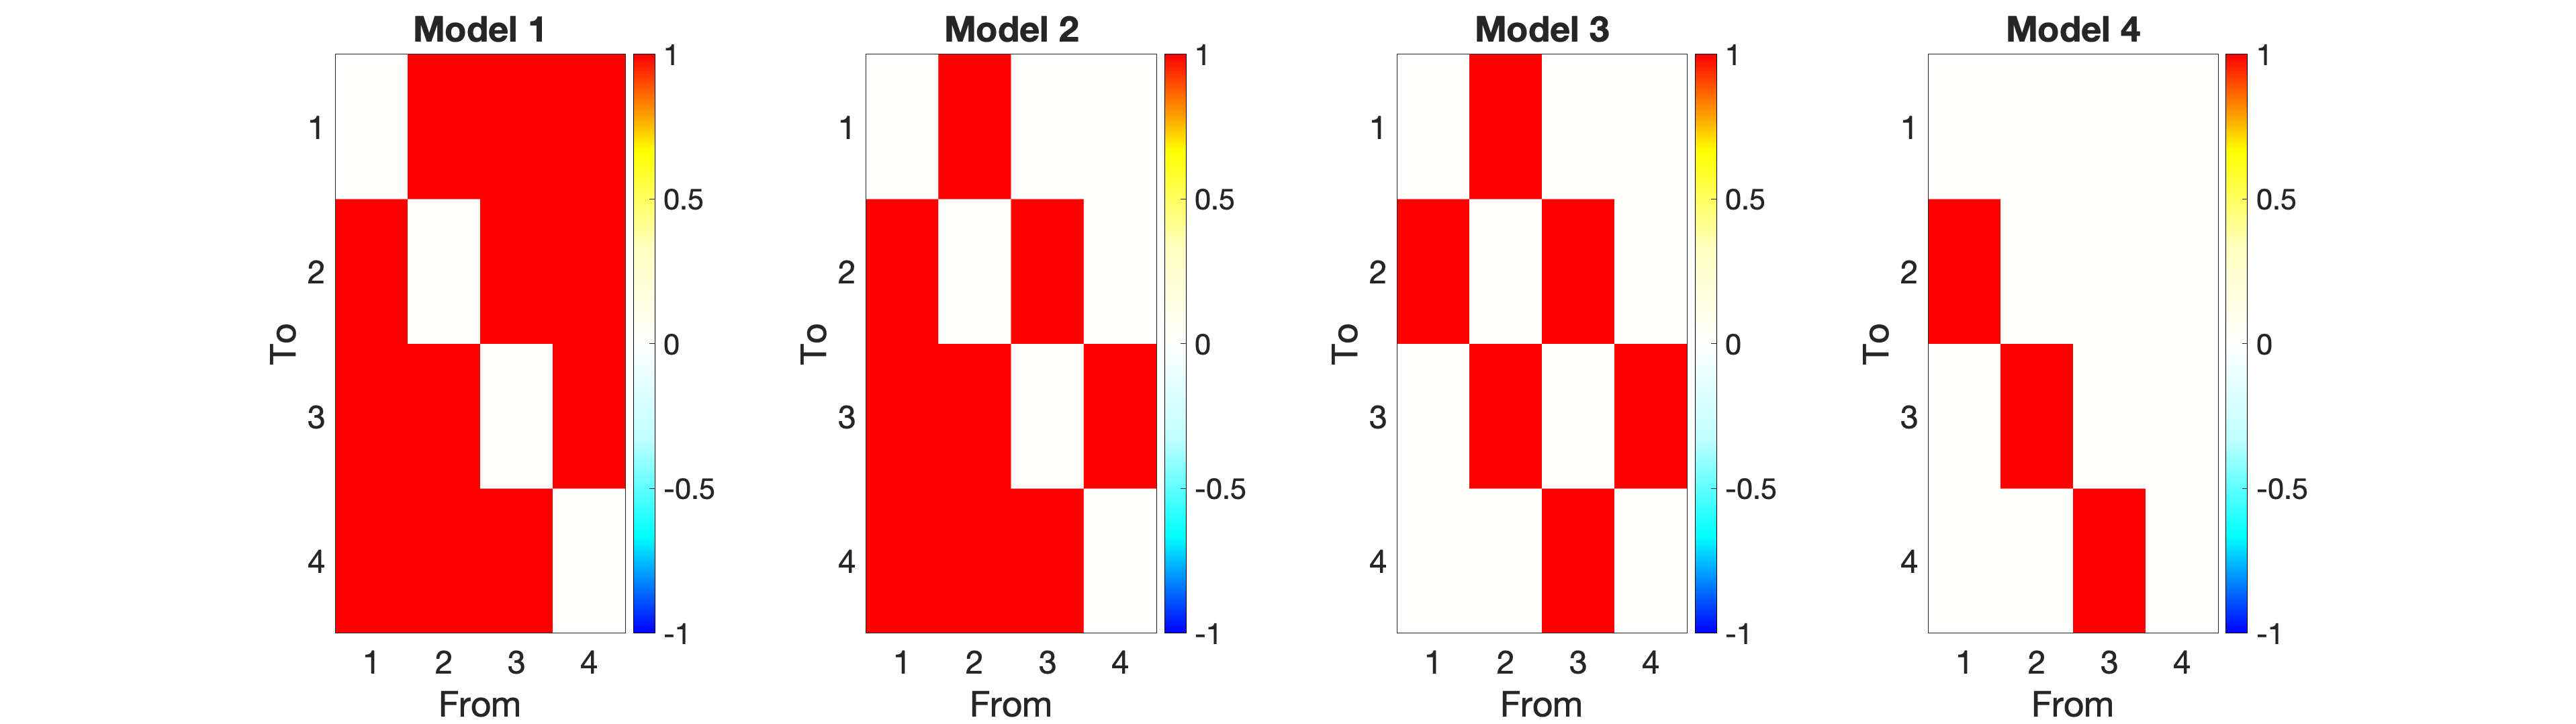

fig = figure();
subplot(1, 4, 1)
plot_connectivity(model1, 0)
title("Model 1")
subplot(1, 4, 2)
plot_connectivity(model2, 0)
title("Model 2")
subplot(1, 4, 3)
plot_connectivity(model3, 0)
title("Model 3")
subplot(1, 4, 4)
plot_connectivity(model4, 0)
title("Model 4")
set(fig,'Units','normalized','Position',[0 0 1 .5]);

Confirm you have the same SNR and TR settings

stim_options.SNR
stim_options.TR

Simulate 20 subjects by

- change true connectivity matrix in `stim_options`

- generate timeseries

- remove input used for the AR(1) process

- replace DCM.a to specify which parameters to estimate

- invert model without pruning (as done in Frässle et al. (2021), HBM)

for i=1:num_sims
    
    warn_counter = 0;
    maxIter = 10;
    origState = warning;
    
    %when sampling random connectivity matrices sometimes activity
    %propogation ends up in singular matrices and fails. To avoid this I
    %added a while loop to resample a connectivity matrix and generate
    %timeseries
    while warn_counter<maxIter
        
        if warn_counter == 0
            fprintf("First try.\n");
        end
        
        % Sample connectivity parameters and make sure they are >0.05
        too_small = 1;
        while too_small
            
            %distribution for connectivity parameters comes from spm_dcm_fmri_priors.m
            A     =  model4 > 0;
            A     =  A - diag(diag(A));
            prior_means = A/(64*nr) - eye(nr,nr)/2;
            prior_sds = sqrt(A*8/nr + eye(nr,nr)/(8*nr));
            
            sampled_as = zeros(stim_options.n);
            for cur_row = 1:stim_options.n
                for cur_col = 1:stim_options.n
                    sampled_as(cur_row, cur_col) = normrnd(prior_means(cur_row, cur_col), prior_sds(cur_row, cur_col));
                end
            end
            
            %make sure only specified connections exist
            stim_options.Tp.A = sampled_as.*model4;
            
            %check and print value of too_small
            too_small = sum(sum(abs(stim_options.Tp.A)>0 & abs(stim_options.Tp.A)<0.05))
        end
       
       
        % Sample hemodynamic parameters from priors specified in
        % spm_dcm_fmri_priors.m
        stim_options.transit = normrnd(0,1/256,[stim_options.n,1]);
        stim_options.decay = normrnd(0,1/256);
        stim_options.epsilon = normrnd(0,1/256);
        
        warning('off');
        [DCM, options] = make_ar1_resting_fmri(stim_options);
        [warnMsg, warnId] = lastwarn;
        
        %if there is a warning then increase and print the counter and try again
        if ~isempty(warnMsg)
            warn_counter = warn_counter + 1
        %if no warning push counter to quit the while loop
        else
            warn_counter = maxIter + 1;
            fprintf("No warnings.\n");
        end
        
        % Clear last warning message
        warning(''); 
    end
    warning(origState);

    %Remove input used for endogenous states
    if isfield(DCM, "U")
        DCM = rmfield(DCM,'U');
    end
      
    %Run standard rDCM
    %Replace matrix to specify which parameters to estimate 
    DCM.a = logical(DCM.Tp.A);
    [output, options] = tapas_rdcm_estimate(DCM, type, options, 1);
    output_all{i} = output;
end

## New simulations